# WELCOME TO V768 - Measuring Vision with Psychophysics

## Lab 4 - Contrast Sensitivity Functions

This lab walks through measuring your own contrast sensitivity function.

### Learning Outcomes

(i.e., what you will be able to do at the end of this lab)

- Describe how threshold and sensitivity are measured from a psychometric curve.

- Measure a contrast sensitivity function.

### Questions

#### A. Computing threshold and sensitivity from a psychometric curve.

- The example in Part A, shows you how to calculate the threshold and sensitivity for a 2AFC task.  To calculate threshold, you simply find the stimulus value at 75% correct.  How would you calculate the threshold if this was a Yes/No task and performance ranged from 0 to 100 percent?

#### B. Measuring a Contrast sensitivity function

- TODO (Clean this up) Write a figure caption for the visualization of fits, the contrast threshold panel and the contrast sensitivity panel.

#### C. Wrap-Up

- Not sure yet.

## Part A. Computing threshold and sensitivity

In Lab 3, you learned about **psychometric functions**. We used the equation 


$$\mathbf{p}=\psi \left(\mathbf{x};\mu ,\sigma ,\gamma ,\lambda \right)=\mathrm{CDF}\left(\mathbf{x};\mu ,\sigma \right)\cdot \left(1-\gamma -\lambda \right)+\gamma$$


where $\psi$ is the psychometric function, $\mathbf{x}$ is the set of stimulus levels (the input of function $\psi$), $\mathbf{p}$ is the set of response probabilities (the output of function $\psi$), $\mu$ is the mean of the underlying cumulative density function (CDF), $\sigma$ is the standard deviation of that CDF, $\gamma$ is the guess rate, and $\lambda$ is the lapse rate.

When we put stimulus levels $\mathbf{x}$ into function $\psi$, we get back a set of response probabilties $\mathbf{p}$. What if instead we want to input a response probability and find out the corresponding stimulus level? To do that, we need to invert our equation.


$$\mathbf{p}=\mathrm{CDF}\left(\mathbf{x}\right)\cdot \left(1-\gamma -\lambda \right)+\gamma$$



$$\mathbf{p}-\gamma =\mathrm{CDF}\left(\mathbf{x}\right)\cdot \left(1-\gamma -\lambda \right)$$



$$\frac{\mathbf{p}-\gamma }{1-\gamma -\lambda }=\mathrm{CDF}\left(\mathbf{x}\right)$$



$$\mathbf{x}={\mathrm{CDF}}^{-1} \left(\frac{\mathbf{p}-\gamma }{1-\gamma -\lambda }\right)$$


Now we know how to use the inverse CDF to find $\mathbf{x}$ given $\mathbf{p}$.

### Step 1. Measure threshold from a psychometric curve

Think back to the 2AFC task from Lab 3. You were forced to choose between left and right. If you guessed, you had a 50% chance of being correct. Thus, chance performance for that task (and similar tasks) is 50%.

Recall that a psychometric function is an ***inferential model***. Therefore, we can infer certain things from a psychometric function about the relationship between a given stimulus feature (e.g., contrast) and a participant's forced-choice responses. One of those things is a participant's **threshold**. For 2AFC tasks like the one from Lab 3, the threshold is typically defined as the stimulus level associated with a response probability of 75%, halfway between chance (50%) and perfect (100%) performance.

As a demonstration, let's define an example psychometric function and find its threshold value.

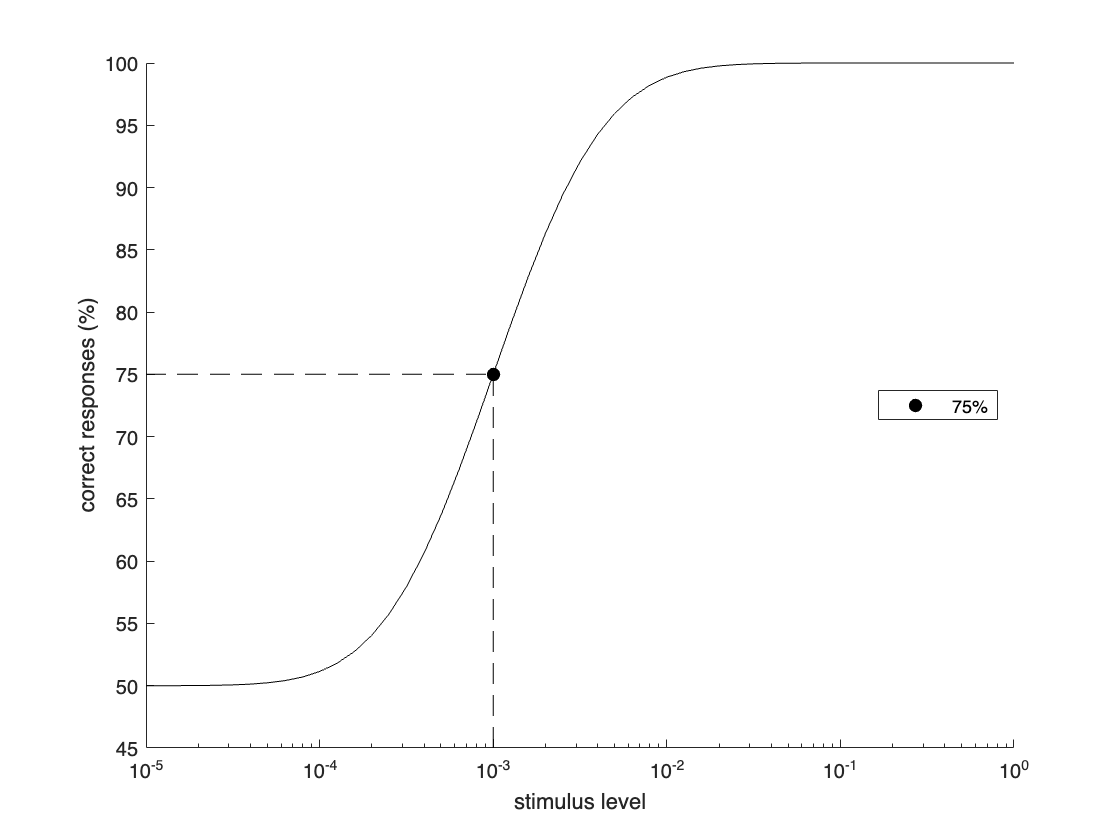

% define psychometric function and its inverse
psyfxn = @(c,x) (normcdf(x, c(1), c(2)) * (1 - c(3) - c(4))) + c(3);
ipsyfxn = @(c,p) norminv((p - c(3))/(1 - c(3) - c(4)), c(1), c(2));
% c(1) = mu
% c(2) = sigma
% c(3) = guess rate
% c(4) = lapse rate

% create an example psychometric curve
psy_mu = -3;
psy_sig = .5;
psy_lapse = 0;
psy_guess = .5;
psy_params = [psy_mu, psy_sig, psy_guess, psy_lapse];
x_curve = 10.^(-5:.1:0);
y_curve = psyfxn(psy_params, log10(x_curve));

% compute the 75% mark for this psychometric curve
thresh_level = 75;
threshold = 10.^(ipsyfxn(psy_params, thresh_level/100));

% plot the example psychometric function
figure; hold on;
plot(x_curve, y_curve*100, 'k')
set(gca,'XScale','log')
ylim([45,100])
xlabel('stimulus level')
ylabel('correct responses (%)')

% add the 75% mark
plot([x_curve(1), threshold], [thresh_level, thresh_level], 'k--')
plot([threshold, threshold], [45, thresh_level], 'k--')
dot_handle = plot(threshold, thresh_level, 'k.', 'MarkerSize',20);
legend(dot_handle, {[num2str(thresh_level) '%']}, 'Location','east')

drawnow

For our example curve, the 75% threshold is:

threshold

threshold = 1.0000e-03

### Step 2. Compute sensitivity from a threshold

Thresholds will be small for spatial frequencies you can see easily, and thresholds will be large for spatial frequencies you have trouble seeing.  This means that when thresholds are small, performance on the task will be better.  And when thresholds are large, performance the task is worse.  Generally this can make interpreting thresholds on a graph difficult -- it is somewhat more intuitive for numbers to go up with good performance and down with bad performance.  As a result, thresholds are often converted into sensitivities by simply taking the reciprocal of threshold.


$$sensitivity = \frac{1}{threshold}$$


sensitivity = 1/threshold

sensitivity = 1000

## Part B. Measuring your own contrast sensitivity function

### Step 1. Data collection

To collect data, open the PsychoPy ".psyexp" file in the folder titled "contrast-sensitivity", and run that experiment. The instructions will appear on the screen before the trials begin. The experiment includes XXX trials measuring contrast sensitivity at 5 spatial frequencies (1cpd, 2cpd, 4cpd, 8cpd, 16cpd).

### Step 2. Load your data

Before running this section of code, find the name of the ".csv" file containing your experiment data, and enter it below.

file_location = '04-contrast-sensitivity-function/contrast-sensitivity/data/';
id = 'demo2_';

psycho_data = table;
files = dir([file_location, id,'*.csv'])

files = 3×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


warning off;
for ff = 1:length(files)
    fprintf('loading %s ...\n',files(ff).name)
    tmp=readtable([files(ff).folder,'/',files(ff).name]);
    psycho_data = [psycho_data; tmp];
end

loading demo2_contrast_sensitivity_2025-01-26_16h15.23.030.csv ...
loading demo2_contrast_sensitivity_2025-01-26_16h34.42.314.csv ...
loading demo2_contrast_sensitivity_2025-01-26_16h43.44.651.csv ...


warning on;

% remove the rows/columns associated with the instructions in psychopy
psycho_data(1,:)=[];
remove = {'notes','begin_experiment_started','begin_experiment_stopped'};
psycho_data(:,remove) = [];

### Step 3. Visualize your performance

For this experiment, the target stimulus was a grating with a contrast of *e* to the power of -1 (approx. 0.37). The participant controlled the contrast of a second grating and pressed a button when the contrast of the two gratings seemed to match. PsychoPy saved the contrast of the controlled grating at the time of response, as well as the initial contrast level of that grating (either high or low).

**Re-organize the psychopy data into a new table for analysis.**

% set some measurements that we'll use to calculate approximate values for the spatial frequencies
viewing_distance = 60; % cm  -- This should be about right for sitting at a desk and looking at a laptop
screen_height = 20; %cm -- For Kate's macbook pro 15 inch
cm2deg = (2*atan2d(screen_height/2,viewing_distance))/screen_height;

% re-organize the psychopy data into a new table for analysis
analyze = table;
analyze.contrast = psycho_data.contrast;
contrast_levels = unique(analyze.contrast);
grating_location = psycho_data.location;
response_location = psycho_data.response_keys;
analyze.correct = (grating_location==1 & strcmp(response_location,'right')) | (grating_location==-1 & strcmp(response_location,'left'));

% calculate the spatial frequency (keep in mind that this is fairly
% approximate)
analyze.sf = 1./(psycho_data.size./2*screen_height*cm2deg);


**Group the data by spatial frequency and contrast**

g = grpstats(analyze,{'contrast','sf'})

g = 30×4 table
                       contrast      sf       GroupCount    mean_correct
                       ________    _______    __________    ____________

    1e-08_0.264206       1e-08     0.26421        36          0.55556   
    1e-08_0.528412       1e-08     0.52841        36          0.47222   
    1e-08_1.05682        1e-08      1.0568        36          0.47222   
    1e-08_2.11365        1e-08      2.1136        36          0.44444   
    1e-08_4.22729        1e-08      4.2273        36          0.44444   
    0.0001_0.264206     0.0001     0.26421        36          0.83333   
    0.0001_0.528412     0.0001     0.52841        36             0.75   
    0.0001_1.05682      0.0001      1.0568        36   

frequencies = unique(g.sf);
g.percent_correct = 100*g.mean_correct;


**Visualize the percent correct per condition (per spatial frequency and contrast)**

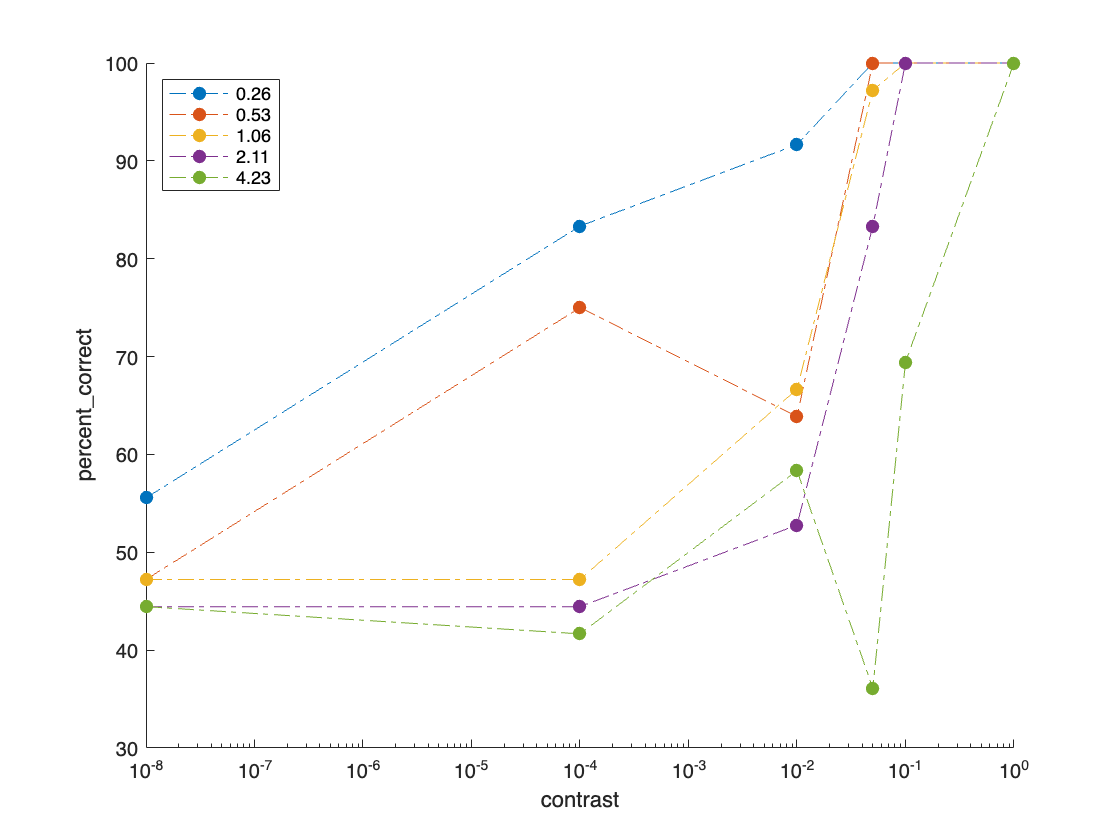

figure(); clf; hold on;
for ff=1:length(frequencies)
    data_lines(ff) = plot(g(g.sf==frequencies(ff),:),"contrast","percent_correct",'LineStyle','-.','marker','.','markersize',20);
end
set(gca,'XScale','log')
legend(num2str(frequencies,'%.2f'),'Location','northwest')
title('')

drawnow;

### Step 4. Fit psychometric curves and compute threshold/sensitivity

In order to calculate the threshold, we need to fit psychometric curves to the data for each spatial frequency and then calculate the threshold (contrast value at 75%).

#### **Fit psychometric curves to the data.**

% TODO grab this from Lab 3

#### **Visualize fits. **

% TODO 

#### **Compute/Visualize threshold.**

% TODO 

#### **Compute/Visualize sensitivity.**

% TODO 